%Golden
load('D:\Xilinx\Vivado_2018_Projs\IMC_CHIP_2023\PCB_v1\MATLAB_CONTROL\Control_Codes\Testing\011_CurrentMirrorFunctionality\analyzeResults\CurrentMirrorFunctionality_v1_analyse_02-Aug-2023_15_44_57.mat');

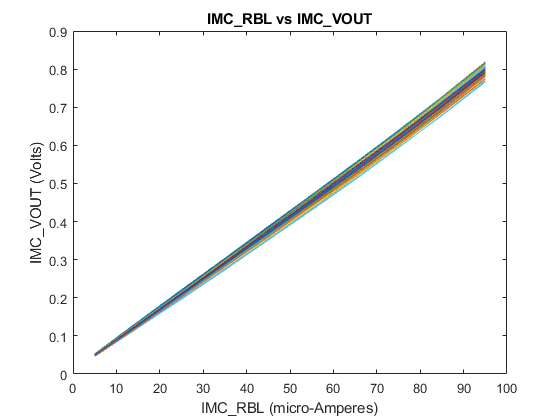

currentValuesAbs_array=[5E-06:10E-06:95E-06]*1E6;%in uA
MAC_xfers=reshape(adc_VPVN,[length(adc_VPVN)/72,72]);
plot(currentValuesAbs_array,MAC_xfers);
title('IMC\_RBL vs IMC\_VOUT');
xlabel('IMC\_RBL (micro-Amperes)');
ylabel('IMC\_VOUT (Volts)');

slopes_unCalib=(MAC_xfers(end,:)-MAC_xfers(1,:))/(currentValuesAbs_array(end)-currentValuesAbs_array(1));
mean_Slope=mean(slopes_unCalib);
disp("mean=",num2str(mean_Slope));

mean=
